clc;
clear;
runtime=5

runtime = 5

Road_length  =1000;
car_number   = 200;
acceleration = 6

acceleration = 6

deceleration =-6.5;
%initial speed
u = 5;
%time limitis
time =300;
%limit speed
lim = 15;

%repeat loop
for l=1:runtime
%initial position of car
J = 1:car_number;
A = rand(1,car_number).*Road_length;
x(J,1) =sort(A);
v(J,1)=u;
%minimum distance between cars
x0 = Road_length/car_number;
num = car_number-1;
delT = 0.1;
k = time / delT
%
average(1) = 0;
t(1) = 0;

for T=2:k
    for J=1:car_number
        if J == car_number
            if J==1
                dis(J,T)= Road_length;
            else
                dis(J,T) = x(1,T-1)-x(J,T-1);
            end
        else
            dis(J,T) = x(J+1,T-1)-x(J,T-1);
        end
        if dis(J,T)<0
            dis(J,T) = Road_length+dis(J,T);
        end
        if dis(J,T) > acceleration * delT
           v(J,T)=v(J,T-1) + acceleration * delT;
        elseif dis(J,T) <= v(J,T-1)
            dis(J,T)=0;
            v(J,T)=0;
        else
           v(J,T)=v(J,T-1)+ deceleration * delT;
        end
        if v(J,T)<0
            v(J,T)=0;
        end
        if v(J,T)>lim
            v(J,T)=lim;
        end
        delta_dis(J,T)=v(J,T)*delT;
        if delta_dis(J,T)>dis(J,T);
            delta_dis(J,T)=dis(J,T);
            v(J,T)=dis(J,T);
        end
        x(J,T)=x(J,T-1)+delta_dis(J,T);
        if x(J,T) > Road_length
           x(J,T)=x(J,T)- Road_length;
        end
    end
      max_speed(T) = max(v(J,T));
      min_speed(T) = min(v(J,T));
      average(T) = sum(v(:,T)) / car_number;
      laverage(l,T)=average(T);
      t(T) = t(T-1) + delT;
end
end

k = 3000

k = 3000

k = 3000

k = 3000

k = 3000

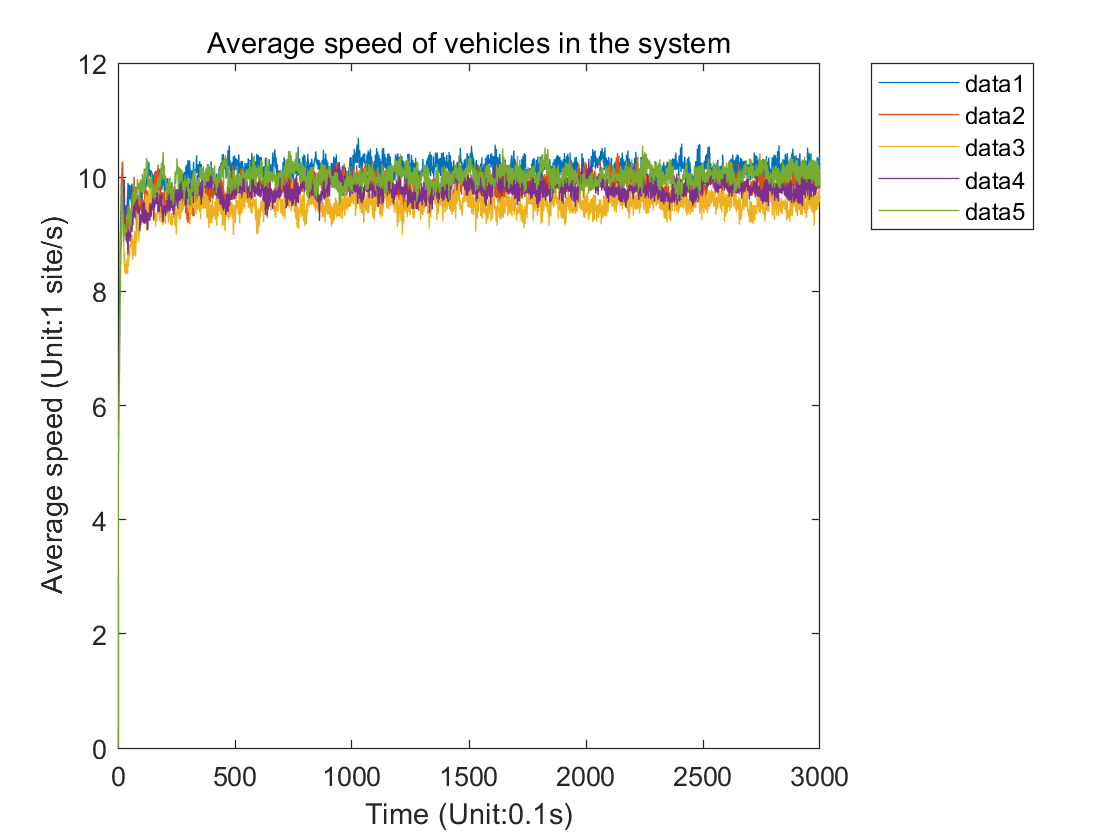


for count=1:runtime
plot(laverage(count,:))
title("Average speed of vehicles in the system")
xlabel('Time (Unit:0.1s)')
ylabel('Average speed (Unit:1 site/s)')
hold on
legend("Location","bestoutside")
end